clc;
clear;

% Snell's Law data
Sinr = [0, 0.06104854, 0.121869343, 0.190808995, 0.241921896, 0.292371705, 0.342020143, 0.406736643, 0.4539905, 0.48480962, 0.515038075, 0.559192903, 0.601815023];
Sini = [0, 0.087155743, 0.173648178, 0.258819045, 0.342020143, 0.422618262, 0.5, 0.573576436, 0.64278761, 0.707106781, 0.766044443, 0.819152044, 0.866025404];

% Error in Sini and Sinr
error_Sini = 0.05;
error_Sinr = 0.05;

% Define incident angles from 0 to 60 degrees
incident_angles_deg = 0:60;
incident_angles_rad = deg2rad(incident_angles_deg);

% Calculate corresponding refracted angles using Snell's Law
n1 = 1; % Refractive index of medium 1
n2 = 1.458; % Refractive index of medium 2
refracted_angles_rad = asin(n1 / n2 * sin(incident_angles_rad));

% Plot the data points with error bars
figure(1);
errorbar(Sinr, Sini, error_Sini*ones(size(Sini)), error_Sini*ones(size(Sini)), error_Sinr*ones(size(Sinr)), error_Sinr*ones(size(Sinr)), 'o');
hold on;

% Fit a line
p = polyfit(Sinr, Sini, 1); % Flipped Sinr and Sini
x_fit = linspace(min(Sinr), max(Sinr), 100);
y_fit = polyval(p, x_fit);
plot(x_fit, y_fit, 'r');

% Calculate the gradient
gradient = p(1);

% Perform error propagation
% Error in gradient (slope)
error_gradient = sqrt((error_Sinr / range(Sinr))^2 + (error_Sini / range(Sini))^2);

% Display the gradient and its error
disp(['Gradient of the best-fit line: ', num2str(gradient)]);

Gradient of the best-fit line: 1.4619


disp(['Error in gradient: ', num2str(error_gradient)]);

Error in gradient: 0.10117


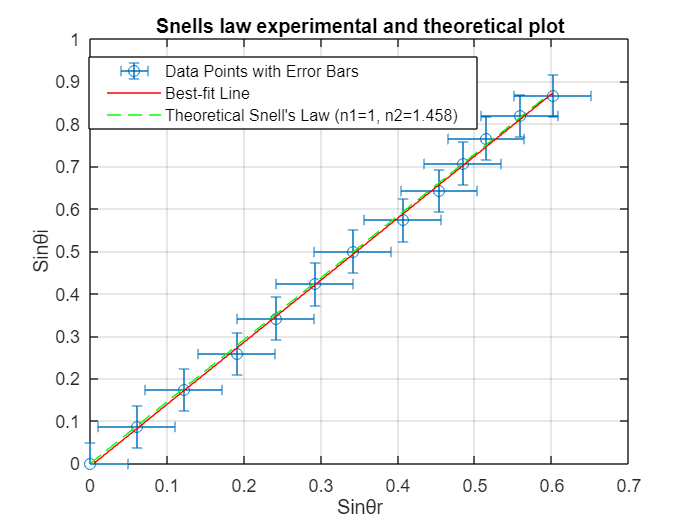


% Plot theoretical Snell's Law
plot( sin(refracted_angles_rad),sin(incident_angles_rad), 'g--');

xlabel('Sinθr');
ylabel('Sinθi');
title('Snells law experimental and theoretical plot');
legend('Data Points with Error Bars', 'Best-fit Line', 'Theoretical Snell''s Law (n1=1, n2=1.458)');
grid on 
xlim([0 0.7])
ylim([0 1])
legend("Position", [0.14856,0.75794,0.51823,0.12788])
hold off

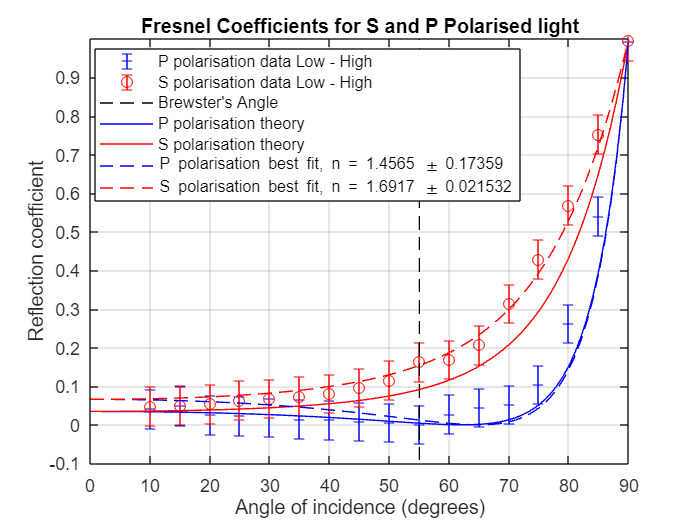


% Freznel Coefficients
AngleOfIncidence = [10,15,20,25,30,35,40,45,50,55,60,65,70,75,80,85,90];
SPolarisationLowHigh = [0.048,0.051,0.054,0.064,0.068,0.074,0.081,0.097,0.116,0.163,0.169,0.207,0.314,0.429,0.569,0.753,0.995];
PPolarisationLowHigh = [0.041,0.049,0.026,0.023,0.019,0.015,0.013,0.009,0.006,0.001,0.028,0.045,0.053,0.104,0.262,0.541,0.993];

figure(2);

hold on

% Plot the measured points using errorbar()
errorbar(AngleOfIncidence, PPolarisationLowHigh, 0.05 * ones(size(PPolarisationLowHigh)), 'b+');
errorbar(AngleOfIncidence, SPolarisationLowHigh, 0.05 * ones(size(PPolarisationLowHigh)), 'ro');

% Add vertical line at Brewster's angle
line([55, 55], ylim, 'Color', 'k', 'LineStyle', '--');

xlabel('Angle of incidence (degrees)');
ylabel('Reflection coefficient');

legend('P polarisation data Low - High', 'S polarisation data Low - High', 'Brewster''s Angle');
axis normal
grid on
box on

% Generate the theory data
AngleOfIncidenceDegrees = 0:1:90;
n = 1.458; % Refractive index

Rs = abs((cosd(AngleOfIncidenceDegrees) - n*sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2)) ./ (cosd(AngleOfIncidenceDegrees) + n*sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2))).^2;
Rp = abs((-n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2)) ./ (n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2))).^2;

% Plot the theory data
plot(AngleOfIncidenceDegrees, Rp, 'blue');
plot(AngleOfIncidenceDegrees, Rs, 'red');

% Find the best fit
SPolFit = fitnlm(AngleOfIncidence', SPolarisationLowHigh', @(n, theta) ReflectionS(n, theta), [1.5]);
PPolFit = fitnlm(AngleOfIncidence', PPolarisationLowHigh', @(n, theta) ReflectionP(n, theta), [1.5]);

% Generate the fit data
SPol_n = SPolFit.Coefficients{1, 1};
PPol_n = PPolFit.Coefficients{1, 1};
SPol_error = SPolFit.Coefficients{1, 2};
PPol_error = PPolFit.Coefficients{1, 2};

RsFit = abs((cosd(AngleOfIncidenceDegrees) - SPol_n*sqrt(1 - (1/SPol_n)*sind(AngleOfIncidenceDegrees).^2)) ./ (cosd(AngleOfIncidenceDegrees) + SPol_n*sqrt(1 - (1/SPol_n)*sind(AngleOfIncidenceDegrees).^2))).^2;
RpFit = abs((-SPol_n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/SPol_n)*sind(AngleOfIncidenceDegrees).^2)) ./ (SPol_n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/SPol_n)*sind(AngleOfIncidenceDegrees).^2))).^2;

% Plot the best fit lines
plot(AngleOfIncidenceDegrees, RpFit, 'blue--');
plot(AngleOfIncidenceDegrees, RsFit, 'red--');

xlabel('Angle of incidence (degrees)');
ylabel('Reflection coefficient');
axis([0, 90, -0.1, 1]);

% Add legend and title
legend('P polarisation data Low - High', 'S polarisation data Low - High', ...
    'Brewster''s Angle', 'P polarisation theory', 'S polarisation theory', ...
    ['P polarisation best fit, n = ', num2str(PPol_n), ' \pm ', num2str(PPol_error)], ...
    ['S polarisation best fit, n = ', num2str(SPol_n), ' \pm ', num2str(SPol_error)]);
title('Fresnel Coefficients for S and P Polarised light');


legend("Position", [0.1633,0.62619,0.55973,0.26992])

hold off

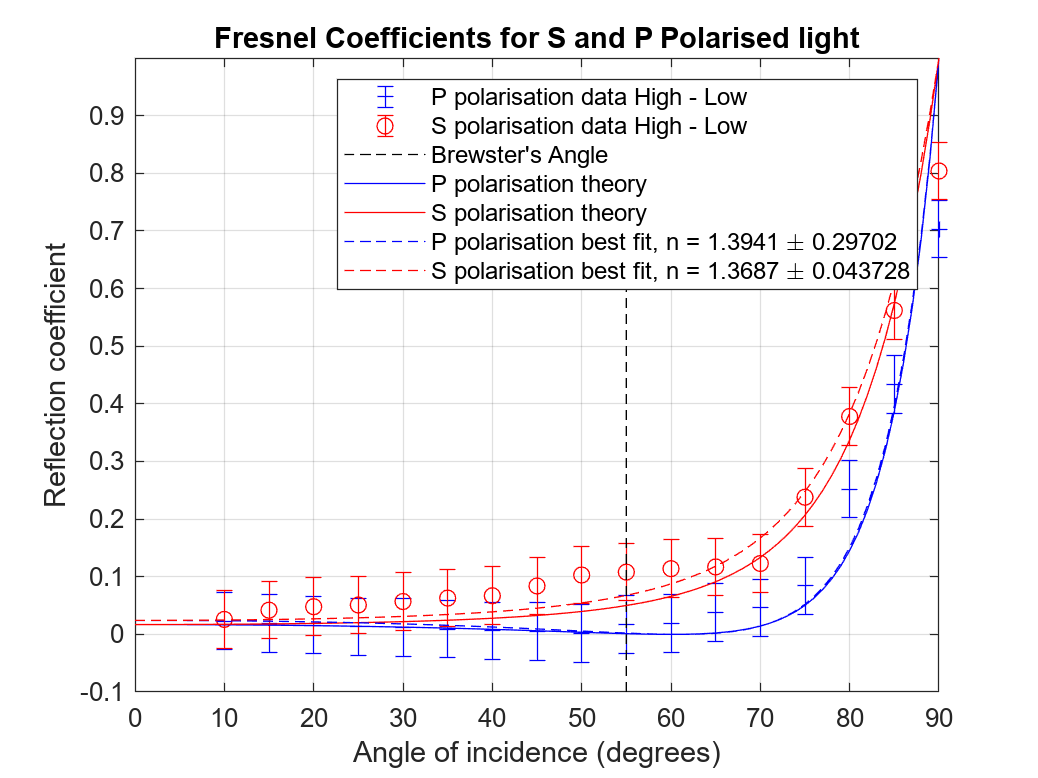


% High to Low index data
AngleOfIncidenceHL = [10,15,20,25,30,35,40,45,50,55,60,65,70,75,80,85,90];
SPolarisationHL = [0.026,0.042,0.048,0.051,0.057,0.063,0.067,0.084,0.103,0.108,0.114,0.117,0.123,0.238,0.378,0.562,0.804];
PPolarisationHL = [0.023,0.019,0.016,0.013,0.012,0.009,0.006,0.005,0.001,0.017,0.019,0.038,0.046,0.084,0.252,0.433,0.703];

% Clear the current figure
clf;
figure(3);

hold on

% Plot the measured points using errorbar()
errorbar(AngleOfIncidenceHL, PPolarisationHL, 0.05 * ones(size(PPolarisationHL)), 'b+');
errorbar(AngleOfIncidenceHL, SPolarisationHL, 0.05 * ones(size(PPolarisationHL)), 'ro');

% Add vertical line at Brewster's angle
line([55, 55], ylim, 'Color', 'k', 'LineStyle', '--');

xlabel('Angle of incidence (degrees)');
ylabel('Reflection coefficient');

legend('P polarisation data High - Low', 'S polarisation data High - Low', 'Brewster''s Angle');
axis normal
grid on
box on

% Generate the theory data
AngleOfIncidenceDegrees = 0:1:90;
n = 1.3; % Refractive index

Rs = abs((cosd(AngleOfIncidenceDegrees) - n*sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2)) ./ (cosd(AngleOfIncidenceDegrees) + n*sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2))).^2;
Rp = abs((-n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2)) ./ (n*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/n)*sind(AngleOfIncidenceDegrees).^2))).^2;

% Plot the theory data
plot(AngleOfIncidenceDegrees, Rp, 'blue');
plot(AngleOfIncidenceDegrees, Rs, 'red');

% Find the best fit
SPolFitHL = fitnlm(AngleOfIncidenceHL', SPolarisationHL', @(n, theta) ReflectionS(n, theta), [1.5]);
PPolFitHL = fitnlm(AngleOfIncidenceHL', PPolarisationHL', @(n, theta) ReflectionP(n, theta), [1.5]);

% Generate the fit data
SPol_nHL = SPolFitHL.Coefficients{1, 1};
PPol_nHL = PPolFitHL.Coefficients{1, 1};
SPol_errorHL = SPolFitHL.Coefficients{1, 2};
PPol_errorHL = PPolFitHL.Coefficients{1, 2};

RsFit = abs((cosd(AngleOfIncidenceDegrees) - SPol_nHL*sqrt(1 - (1/SPol_nHL)*sind(AngleOfIncidenceDegrees).^2)) ./ (cosd(AngleOfIncidenceDegrees) + SPol_nHL*sqrt(1 - (1/SPol_nHL)*sind(AngleOfIncidenceDegrees).^2))).^2;
RpFit = abs((-SPol_nHL*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/SPol_nHL)*sind(AngleOfIncidenceDegrees).^2)) ./ (SPol_nHL*cosd(AngleOfIncidenceDegrees) + sqrt(1 - (1/SPol_nHL)*sind(AngleOfIncidenceDegrees).^2))).^2;

% Plot the best fit lines
plot(AngleOfIncidenceDegrees, RpFit, 'blue--');
plot(AngleOfIncidenceDegrees, RsFit, 'red--');

xlabel('Angle of incidence (degrees)');
ylabel('Reflection coefficient');
axis([0, 90, -0.1, 1]);

% Add legend and title
legend('P polarisation data High - Low', 'S polarisation data High - Low', ...
    'Brewster''s Angle', 'P polarisation theory', 'S polarisation theory', ...
    ['P polarisation best fit, n = ', num2str(PPol_nHL), ' \pm ', num2str(PPol_errorHL)], ...
    ['S polarisation best fit, n = ', num2str(SPol_nHL), ' \pm ', num2str(SPol_errorHL)]);
title('Fresnel Coefficients for S and P Polarised light');
hold off




% Define the functions for the Fresnel coefficients

function [ReflectionDataS] = ReflectionS(n2, theta)
    ReflectionDataS = abs((cosd(theta) - n2*sqrt(1 - (1/n2)*sind(theta).^2)) ./ (cosd(theta) + n2*sqrt(1 - (1/n2)*sind(theta).^2))).^2;
end

function [ReflectionDataP] = ReflectionP(n2, theta)
    ReflectionDataP = abs((-n2*cosd(theta) + sqrt(1 - (1/n2)*sind(theta).^2)) ./ (n2*cosd(theta) + sqrt(1 - (1/n2)*sind(theta).^2))).^2;
end

